# Laboratorium 7-8

Tadeusz Chmielik 324856

Piotr Sienkiewicz 324887 

## Przygotowanie wzorcowych wektorów cech

### Wczytanie nagrania

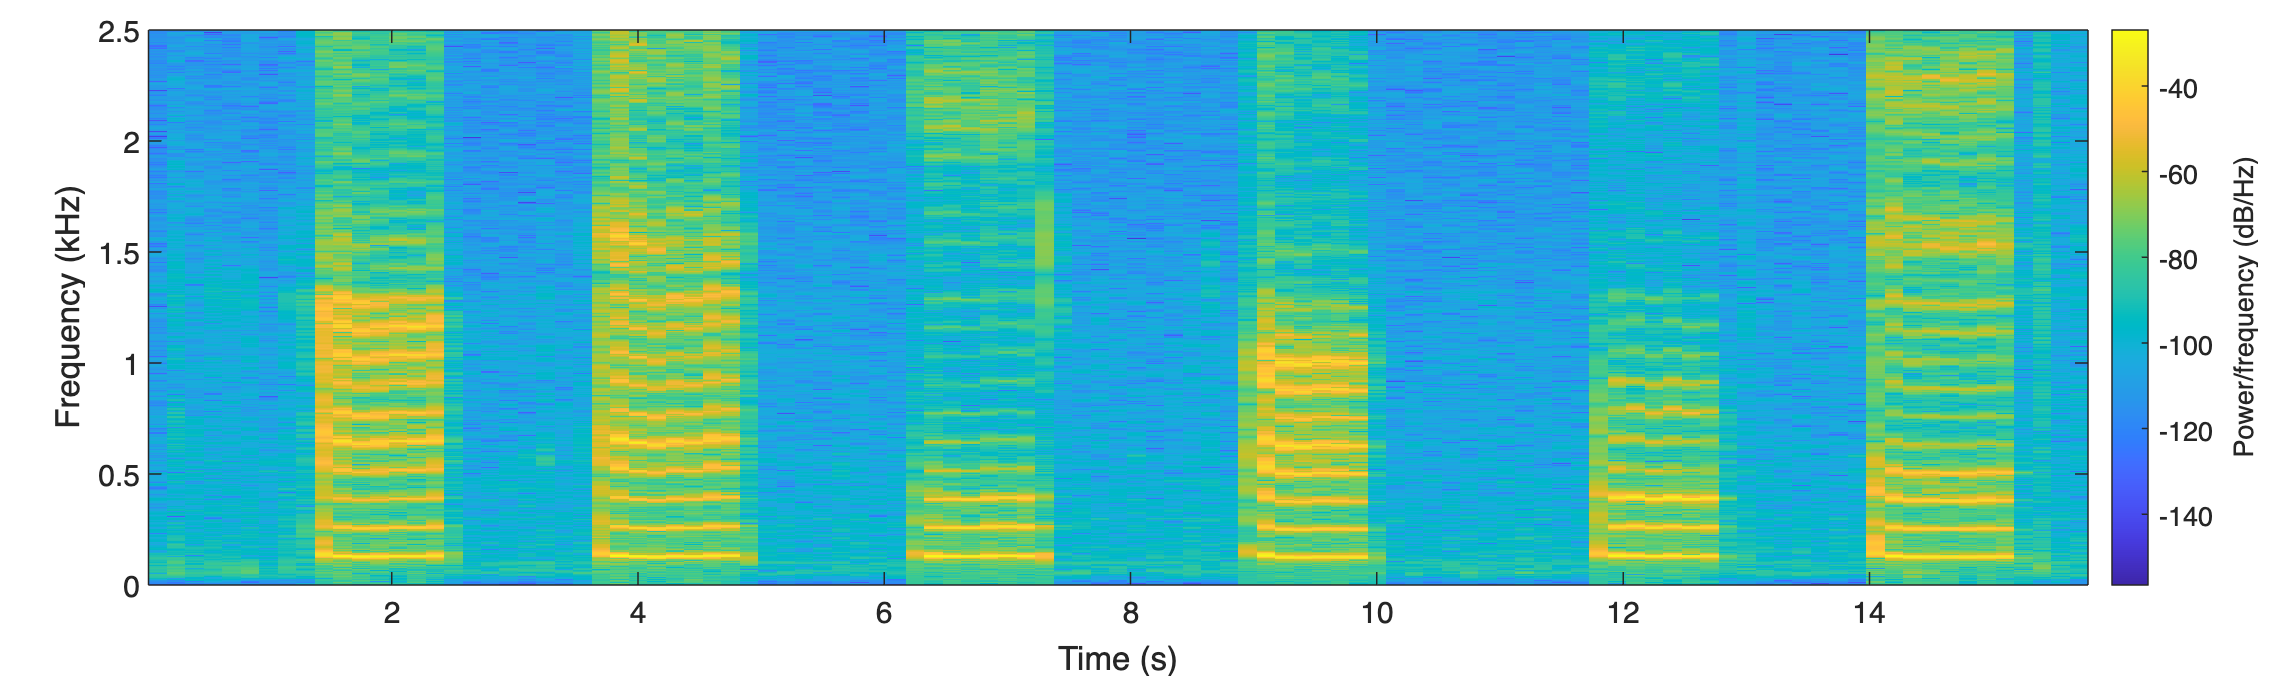

[x, fs] = audioread("recordings/my_aeiouy_3.m4a");
win = round(fs * 0.2);

[s, f, t] = spectrogram(x, win, win / 4, [], fs, 'yaxis');

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
spectrogram(x, win, win/4, [], fs, 'yaxis');
ylim([0 2.5]);

### Etykietowanie danych

W kolejnych kolumnach macierzy znajdują się:

- numer okienka

- numer prążka

- częstotliwość prążka

- numer etykiety

Częstotliwość bazowa dla danego okienka wyznaczana jest przez podzielenie częstotliwości prążka przez jego numer.

sel = [
     11, 9, 1165, 1
     12, 9, 1145, 1
     13, 9, 1160, 1
     14, 9, 1167, 1
    
    26, 5,  650, 2
    27, 5,  640, 2
    28, 5,  628, 2
    29, 5,  645, 2
    
    43,  3,  385, 3
    44,  3,  387, 3
    45,  3,  385, 3
    46,  3,  391, 3
    
    62, 5,  627, 4 
    63, 5,  622, 4
    64, 5,  630, 4
    65, 5,  630, 4
    
    80,  3,  390, 5
    81,  3,  395, 5
    82,  3,  386, 5
    83,  3,  393, 5
    
    95,  3,  387, 6
    96,  3,  376, 6
    97,  3,  380, 6
    98,  3,  377, 6
];

Dodatkowo określamy same etykiety dla naszych danych:

labels = ['a', 'e', 'i', 'o', 'u', 'y'];

### Wyznaczenie wektorów cech

Prostą cechą dla głosek dźwięcznych jest rozkład energii sygnału w kolejnych harmonicznych częstotliwości bazowej (F0). Znając jej wartość można wyznaczyć położenie harmonicznych i odczytać z transformaty Fouriera ich amplitudę bądź energię.

% liczba harmonicznych do analizy
n_peaks = 20;

% liczba próbek uczących
n_frames = size(sel, 1);

% macierz z wektorami cech: każda kolumna to wektor dla kolejnej próbki
feats = zeros(n_frames, n_peaks);


for row = 1:n_frames
    % wyliczenie częstotliwości bazowej
    f0 = sel(row, 3) / sel(row, 2);

    % ekstrakcja ramki ze spektrogramu
    frame_id = sel(row, 1);
    frame = abs(s(:, frame_id));

    % odczyt wartości amplitudy dla kolejnych harmonicznych
    feats(row, :) = interp1(f, frame, (1:n_peaks) * f0);

    % normalizacja amplitud
    feats(row, :) = feats(row, :) / max(feats(row, :));
end

### Wizualizacja

Wektory cech

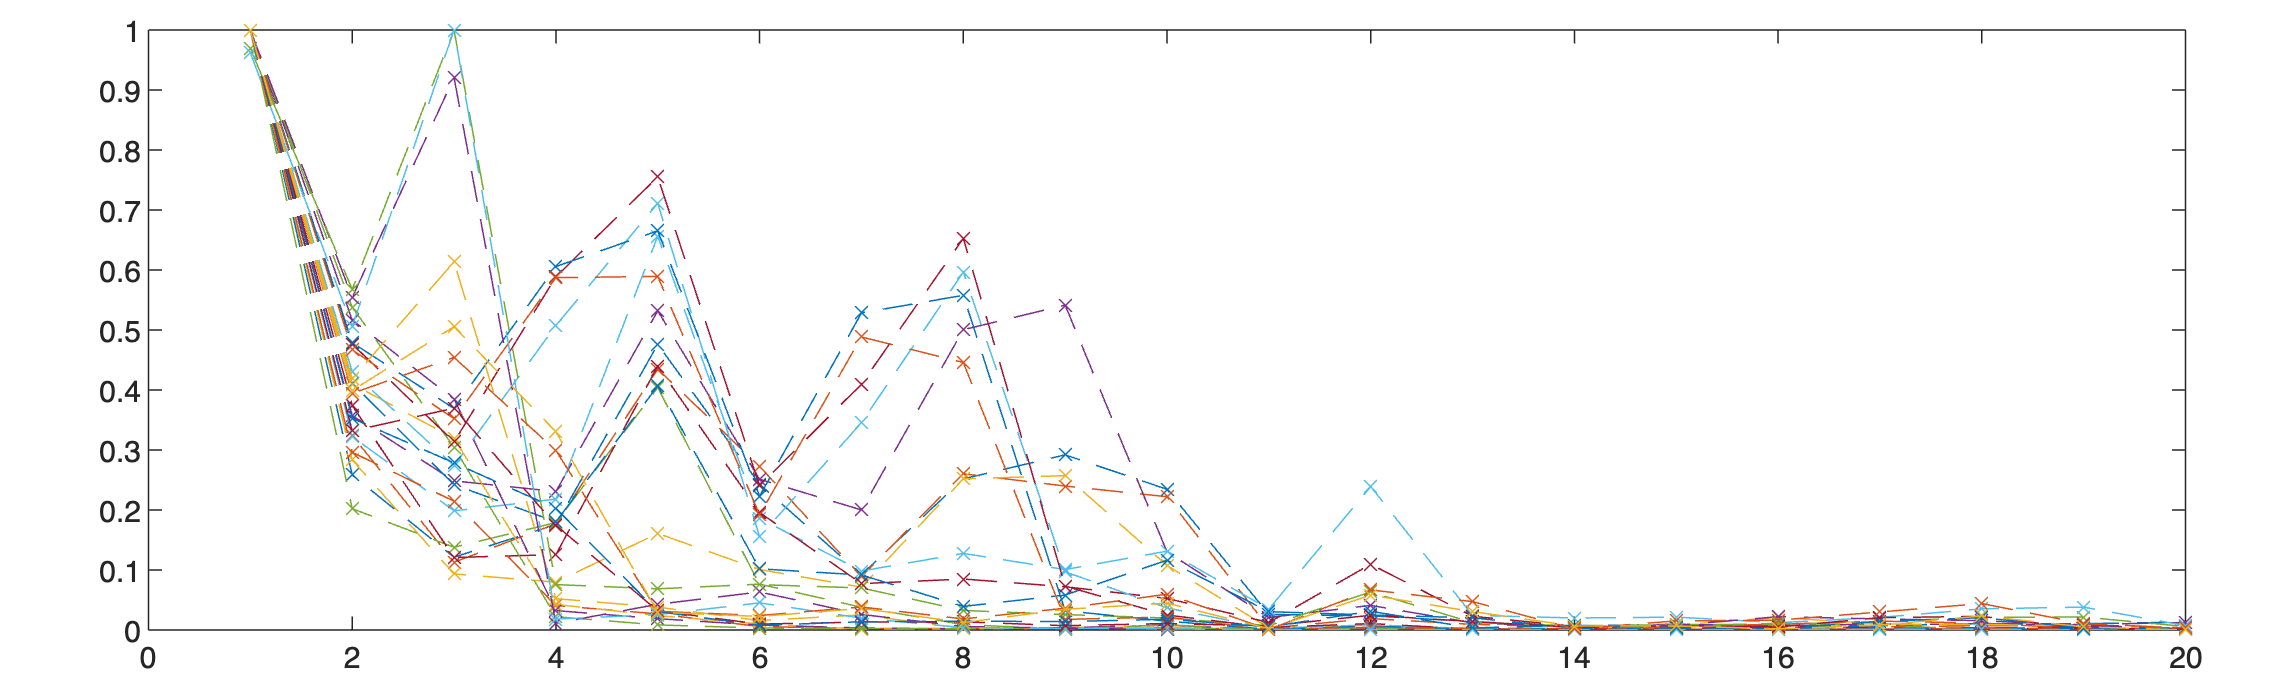

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(feats', 'x--');

Wzajemne odległości między wektorami - wybór metryki ma znaczenie!

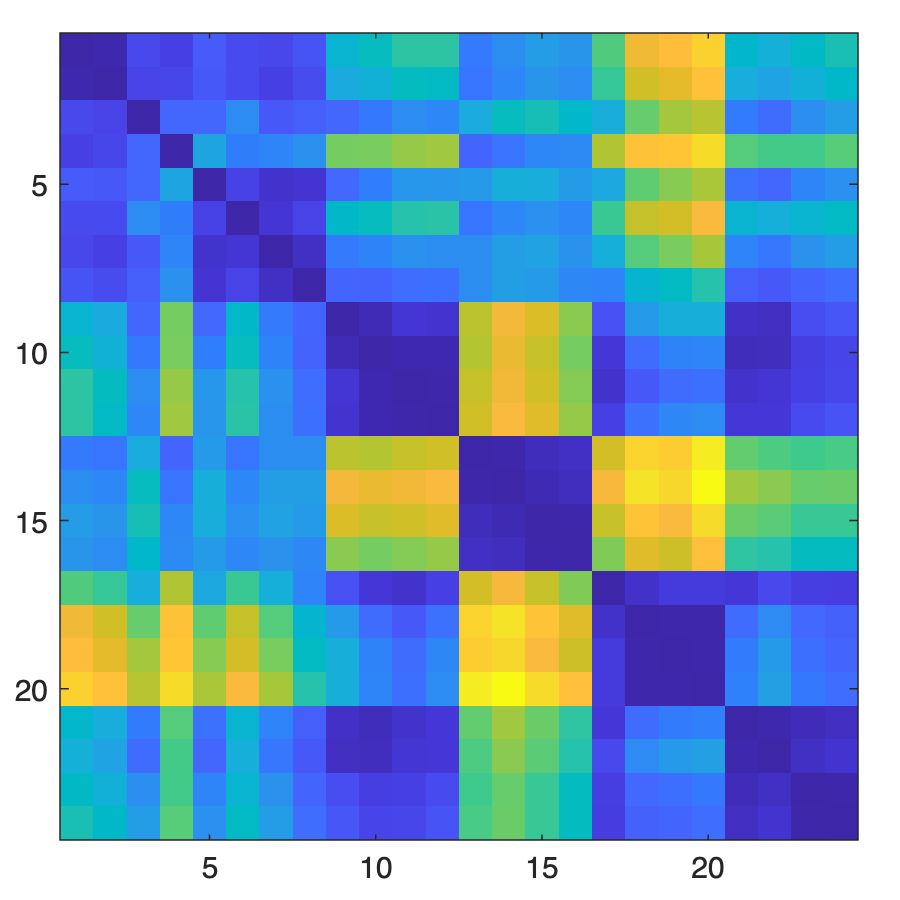

figure("Position", [0 0 300 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
imagesc(pdist2(feats, feats, 'cosine'));

## Analiza nagrania

### Wczytanie nagrania

[x, fs] = audioread("recordings/Metal_1.m4a");

### Segmentacja głosek dźwięcznych w nagraniu

Funkcja geVoicedSegments powinna zwracać macierz, w której każdy wiersz odpowiada znalezionej głosce dźwięcznej, a w kolumnach są po kolei:

- indeks pierwszej próbki 

- indeks ostatniej próbki

- częstotliwość bazowa

s = getVoicedSegments(x, fs);

### Wyznaczenie wektorów cech dla poszczególnych głosek

Algorytm identyczny z użytym do wyznaczenia cech wzorcowych:

- wyznaczenie spektrum sygnału i jego aplitudy

- wybór wartości odpowiadających harmonicznym

- normalizacja wartości

s_count = size(s, 1);

feat = zeros(s_count, n_peaks);
for seg = 1:s_count
    t1 = s(seg, 1);
    t2 = s(seg, 2);
    f0 = s(seg, 3);
    tmp = x(t1:t2);
    [f, A] = getAmp(tmp, fs);
    
    tmp_f = interp1(f, A, (1:n_peaks) * f0);
    feat(seg, :) = tmp_f / max(tmp_f);
end

### Odległości pomiędzy próbkami z nagrania a wzorcem

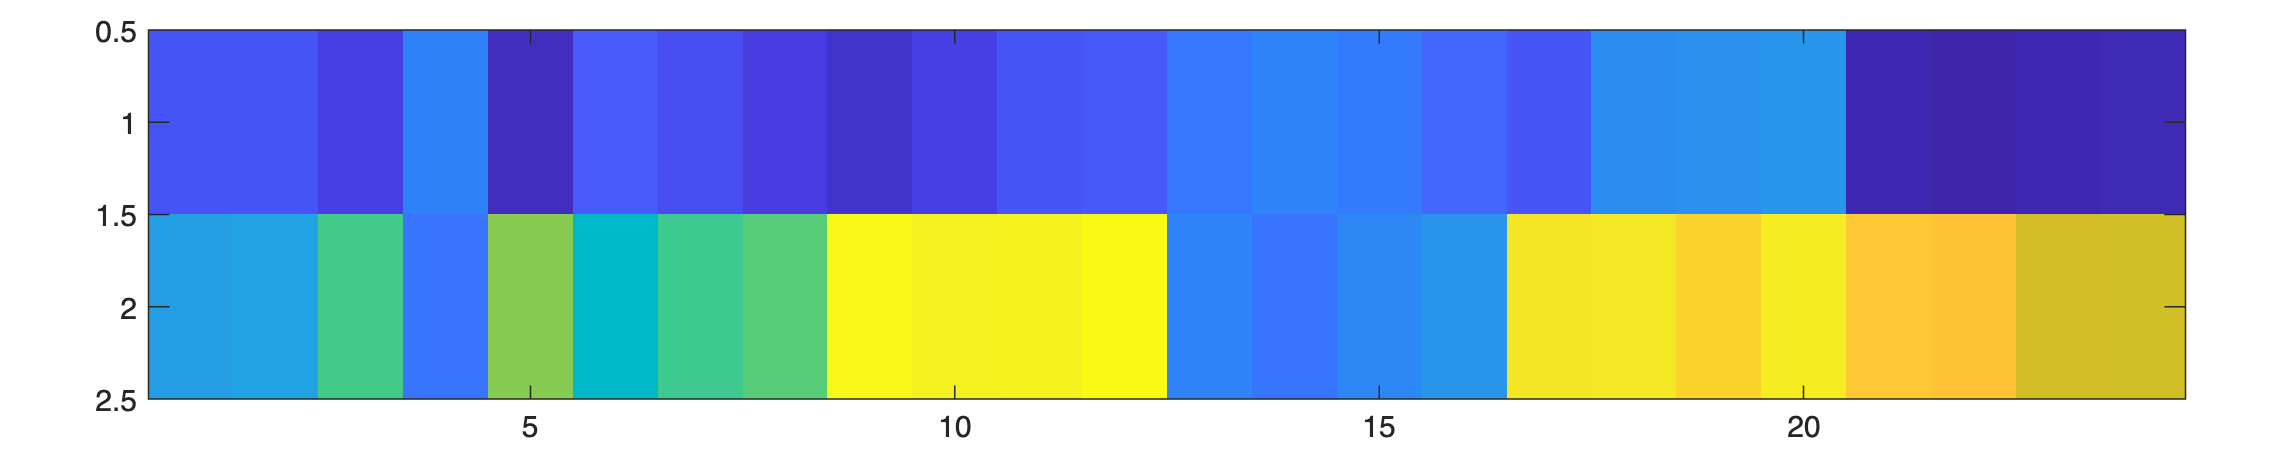

figure("Position", [0 0 1000 200]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
imagesc(pdist2(feat, feats, 'cosine'));

### Klasyfikacja próbek

ret = [];

for seg = 1:s_count
    query = feat(seg, :);
    cls = classify(query, feats, sel(:, 4));
    if ~isnan(cls)
        ret = [ret, labels(cls)];
    end
end

ret

ret = 'ya'

cls_word(ret)

ans = "Metal"

## Funkcje do implementacji

function s = getVoicedSegments(x, fs)
    % Parametry
    win = round(0.03 * fs);  
    hop = round(0.01 * fs);  
    energy_thresh = 0.06;    
    zcr_thresh = 0.3;        

    % Detekcja dźwięku 
    ste = conv(x.^2, ones(1,win), 'same');
    ste = ste / max(ste); 
    str = sqrt(ste);

    lbls = zeros(1, length(str));
    lbls(str > energy_thresh) = 1;

    % Podział na okna i ZCR 
    num_windows = floor((length(x) - win) / hop) + 1;
    voiced = false(1, num_windows);

    for i = 1:num_windows
        idx = (i-1)*hop + 1 : (i-1)*hop + win;

        if mean(lbls(idx)) > 0.5
            segment = x(idx);
            zcr = zerocrossrate(segment);
            if zcr < zcr_thresh
                voiced(i) = true;
            end
        end
    end

    % Wydzielenie głosek dźwięcznych 
    changes = diff([0 voiced 0]);
    starts = find(changes == 1);
    ends = find(changes == -1) - 1;

    s = [];

    for i = 1:length(starts)
        start_idx = (starts(i)-1)*hop + 1;
        end_idx = min((ends(i)-1)*hop + win, length(x));
        segment = x(start_idx:end_idx);

        if length(segment) < fs * 0.05
            continue;
        end

        [f0, ~] = pitch(segment, fs, ...
            'Method', 'NCF', ...
            'Range', [50, 400], ...
            'WindowLength', win, ...
            'OverlapLength', win - hop);

        f0_mean = mean(f0(f0 > 0));

        if isempty(f0_mean) || isnan(f0_mean)
            continue;
        end

        s(end+1, :) = [start_idx, end_idx, f0_mean]; 
    end
end


function cls = classify(query, features, ids)
% klasyfikacja pojedynczej próbki
% - query: badany wektor cech Nx1
% - features: wektory treningowe (referencyjne) NxK
% - ids: identyfikatory klasy Nx1

    d = pdist2(query, features, 'cosine');
    [d_min, min_id] = min(d, [], 2);
    if d_min < 0.5
        cls = ids(min_id);
    else
        cls = NaN; 
    end
end


function word = cls_word(voiced)

    switch voiced
        case "a"
            word = "Ala";
        case "aa"
            word = "Mata";
        case "ya"
            word = "Metal";
        case "o"
            word = "Kot";
    end
    
end


## Funkcje pomocnicze

function [f, A] = getAmp(x, fs)
    L = floor(length(x) / 2) * 2;
    Y = fft(x);     % transformata Fouriera

    A = abs(Y);     % amplituda sygnału

    A = A/L;        % normalizacja amplitudy

    A = A(1:L/2+1); % wycięcie istotnej części spektrum
    A(2:end-1) = 2*A(2:end-1);

    f_step = fs/L;     % zmiana częstotliwości
    f = 0:f_step:fs/2; % oś częstotliwości do wykresu
end

function D = distEmd( X, Y )
    % source: http://www.cs.columbia.edu/~mmerler/project/code/pdist2.m

    Xcdf = cumsum(X,2);
    Ycdf = cumsum(Y,2);
    
    m = size(X,1);  n = size(Y,1);
    mOnes = ones(1,m); D = zeros(m,n);
    for i=1:n
      ycdf = Ycdf(i,:);
      ycdfRep = ycdf( mOnes, : );
      D(:,i) = sum(abs(Xcdf - ycdfRep),2);
    end

end